clear

distance = 3;

p = nsidedpoly(3, 'Center', [0 ,0], 'SideLength', 1); % define the triangle

points = [p.Vertices zeros(3,1)]; % store in array

scatter3(points(:,1), points(:,2), points(:,3), "filled", DisplayName="Sensor Base") % plot triangle
axis equal
hold on

Enter the measurements read by the time of flight sensors:

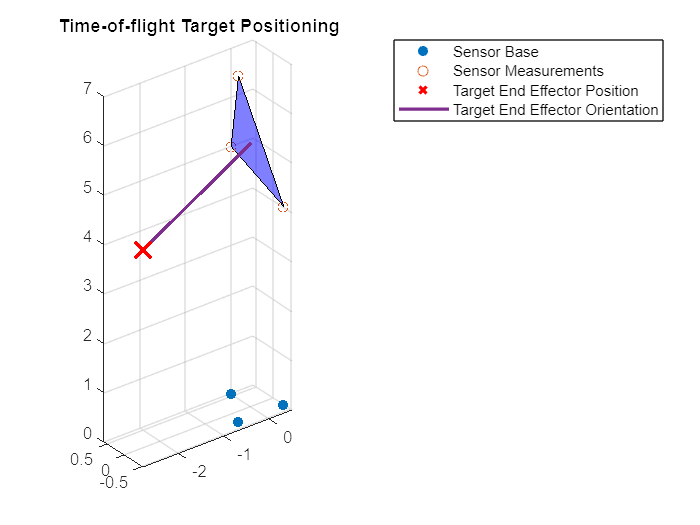

sensor_distances = [7;
                     5;
                     4]; % enter distances read by time of flight sensors

% transform the sensors bases to the measurement locations
sensed_points = points;
sensed_points(:,3) = sensed_points(:,3)+sensor_distances;

% plot laser measurement points
scatter3(sensed_points(:,1), sensed_points(:,2), sensed_points(:,3), "DisplayName", "Sensor Measurements")
patch(sensed_points(:,1),sensed_points(:,2),sensed_points(:,3), 'blue', "FaceAlpha", 0.5, "HandleVisibility", "Off")

% plot centroid
centroid = sum(sensed_points, 1)/3;
% scatter3(centroid(1), centroid(2), centroid(3), 200, "green", "filled")

% Find the angle of the plane:
A = sensed_points(1,:);
B = sensed_points(2,:);
C = sensed_points(3,:);


% Calculate the vectors AB and AC
AB = B - A;
AC = C - A;

% Calculate the cross product of AB and AC to obtain the normal vector
N = cross(AB, AC);

% Obtain the coefficients of the plane equation
A_coeff = N(1);
B_coeff = N(2);
C_coeff = N(3);
D_coeff = -dot(N, A);

% fprintf('Equation of the plane: %.2f*x + %.2f*y + %.2f*z + %.2f = 0\n', A_coeff, B_coeff, C_coeff, D_coeff);

% Find target center position
normal_direction = [A_coeff B_coeff C_coeff] ./ norm([A_coeff B_coeff C_coeff]);

new_center = centroid + distance*normal_direction;
scatter3(new_center(1), new_center(2), new_center(3), 200, "rX", 'LineWidth', 2, "DisplayName","Target End Effector Position")
plot3([centroid(1) new_center(1)], [centroid(2) new_center(2)], [centroid(3) new_center(3)], "LineWidth", 2, "DisplayName","Target End Effector Orientation")
% xlim([-5 5])
% ylim([-5 5])
% zlim([0 10])
legend()
title("Time-of-flight Target Positioning")
hold off